# Segmentation

### COLOR SEGMENTATION

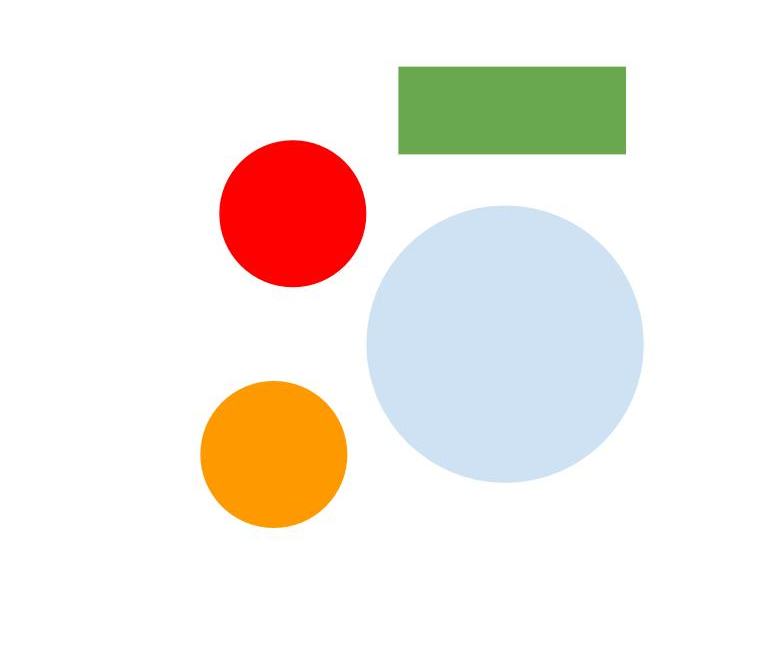

i = imread('color_segmentation.jpg');
imshow(i);

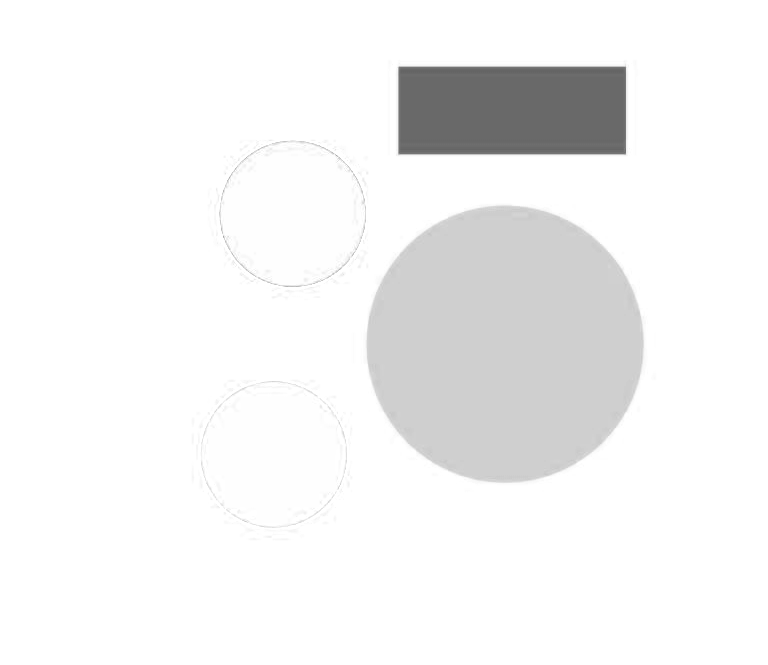


r = i(:, :, 1);
imshow(r);

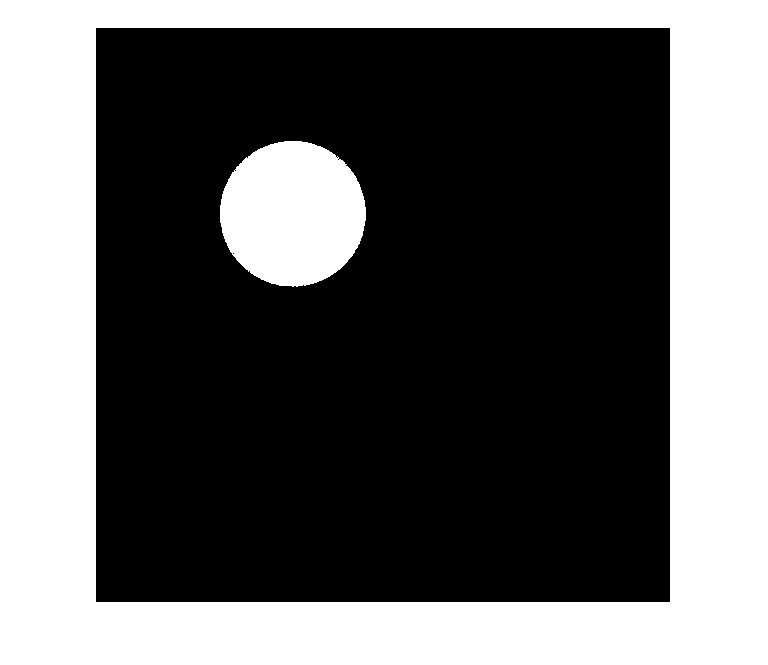


g = i(:, :, 2);
g = ~ imbinarize(g, 0.1);
imshow(g);

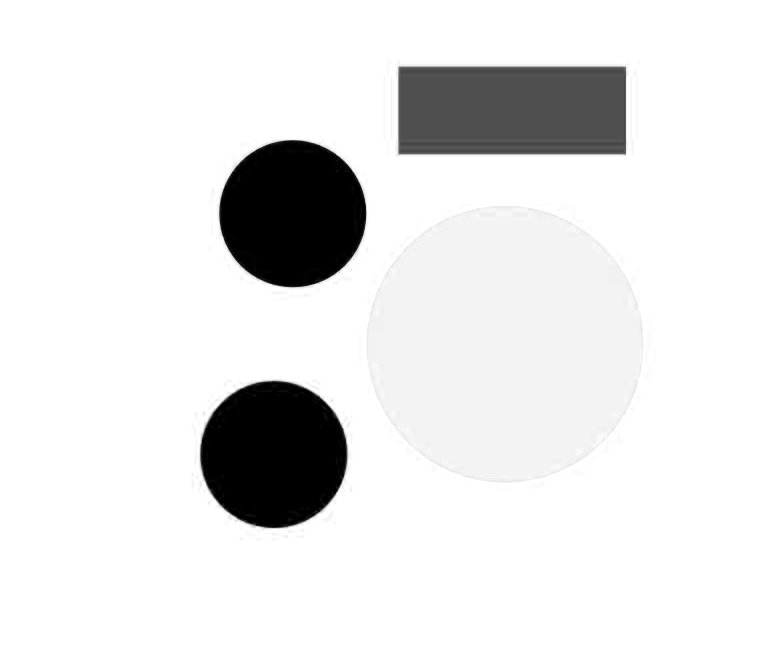


b = i(:, :, 3);
imshow(b);


[L, N] = bwlabel(g);
stats = regionprops(L,'Centroid',...
    'MajorAxisLength','MinorAxisLength')

stats = struct with fields:
           Centroid: [197.3440 186.2546]
    MajorAxisLength: 145.7993
    MinorAxisLength: 145.4605



center = stats.Centroid

center =   197.3440  186.2546


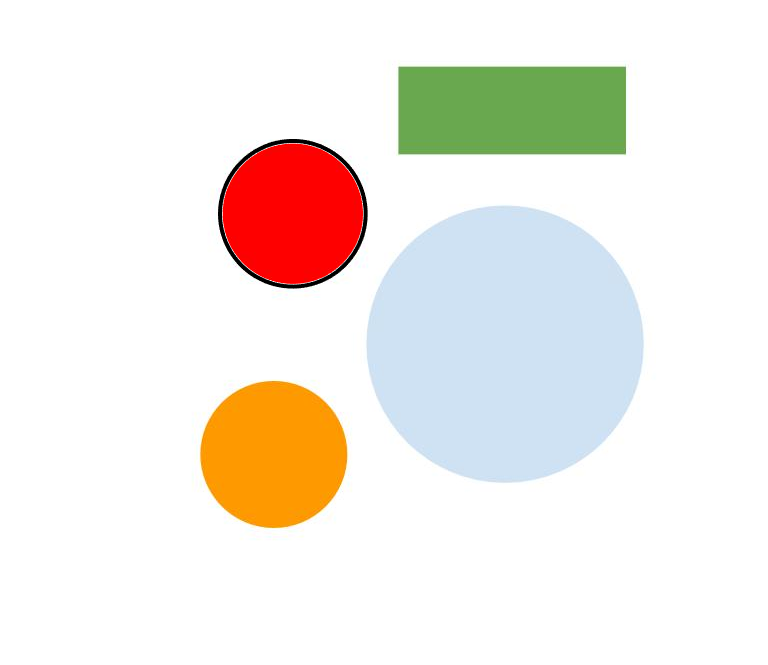

diameter = (stats.MajorAxisLength + ...
    stats.MinorAxisLength) / 2;

imshow(i)
hold on;
viscircles(center, diameter / 2, ...
    'EdgeColor', 'k', 'LineWidth', 3);
hold off;

### CLEANING

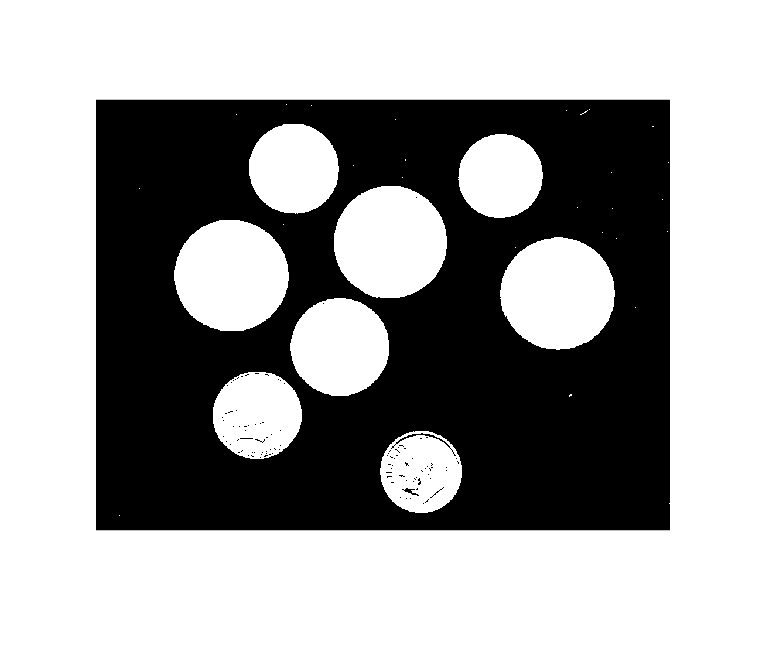

i = imread('coins.png');
bin = imbinarize(i, 0.3);
imshow(bin);

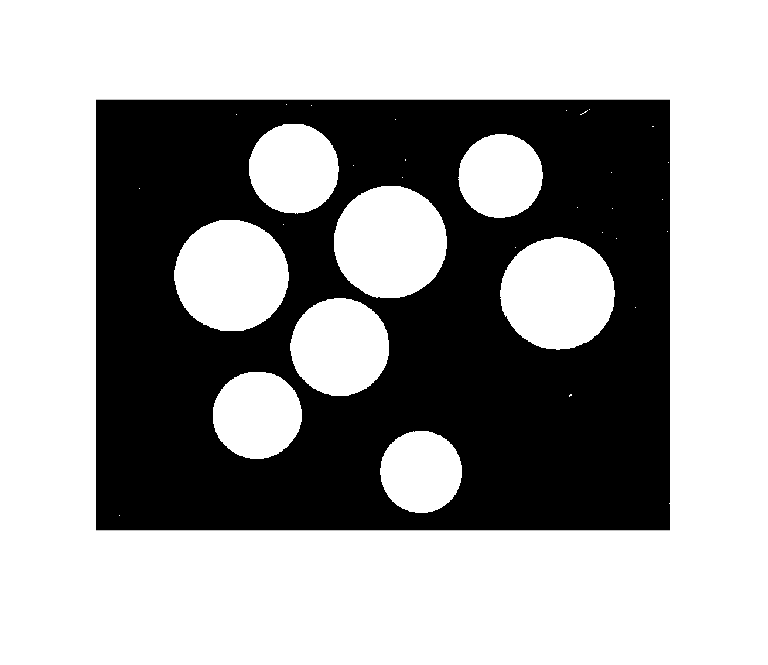


filled = imfill(bin, 'holes');
imshow(filled);

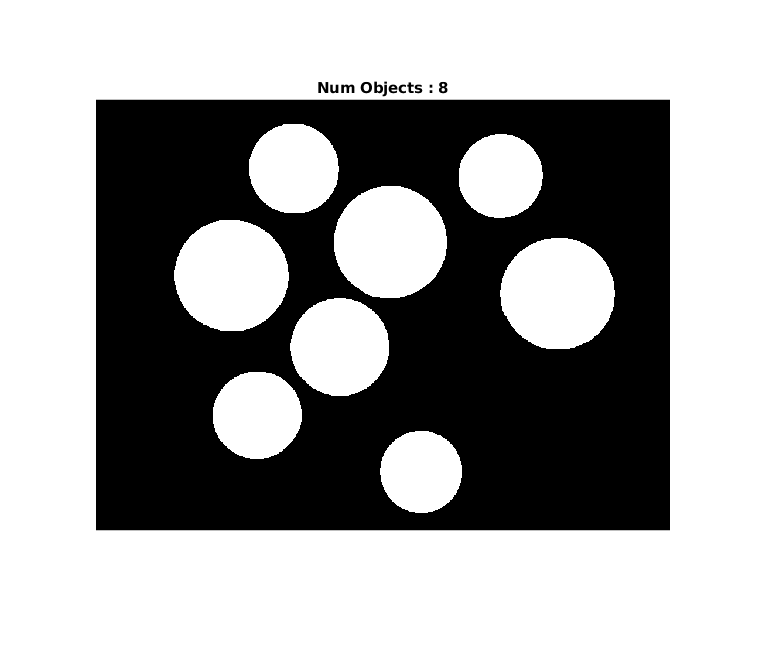


SE = strel('disk', 10);
seg = imopen(filled, SE);
imshow(seg)

[L, N] = bwlabel(seg);
title(strcat("Num Objects : ", string(N)))